# Ruis verwijderen van video.

## Laad video in.

V1 = read(VideoReader('traffic.mp4'));
size(V1)   % Grootte van de tensor.

ans =    180   320     3   505


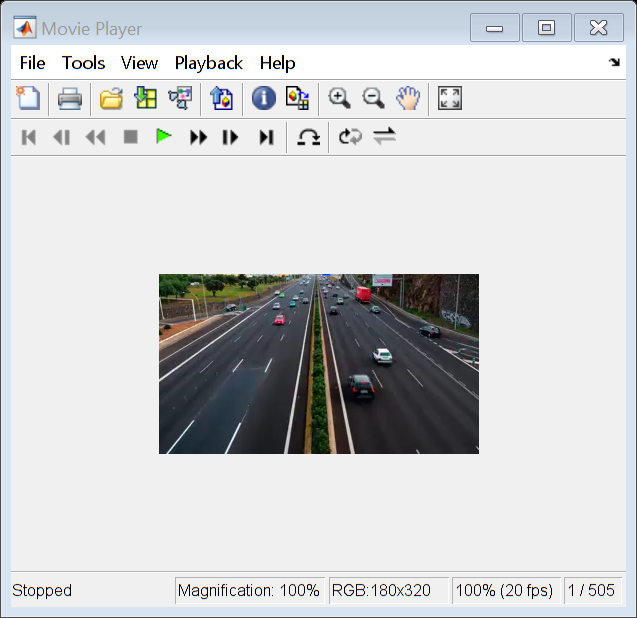

implay(V1) % Speel video af.

## Rang-1 benadering.

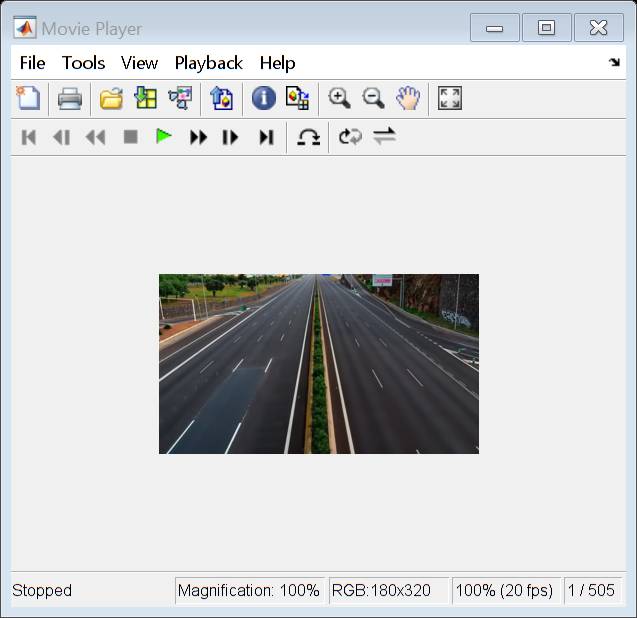

R = 1;
V2 = reshape(V1, [], size(V1, 4));         % Zet om in matrix.
[U,S,V] = svd(double(V2)/255,'econ');      % Bereken SWO.
V3 = U(:, 1:R) * S(1:R, 1:R) * V(:, 1:R)'; % Rang-R benadering.
V4 = reshape(V3, size(V1));                % Zet terug om in tensor.
implay(V4)                                 % Speel video af.